# **Community Growth Code**

#### **Part 1. Find ATP values to corresponding biomass yields & NH3 flux & CUE/NUE**

MATmodel = 'Comm10_Model.mat';

chitinExRxn = 'EX_cpd11683_e0';
nagExRxn = 'EX_cpd00122_e0';
glcExRxn = 'EX_cpd00027_e0';
CO2ExRxn = 'EX_cpd00011_e0';
NH3ExRxn = 'EX_cpd00013_e0';

mediaRxns = {'EX_cpd00001_e0';'EX_cpd00007_e0';'EX_cpd00009_e0';'EX_cpd00011_e0';'EX_cpd00013_e0';...
    'EX_cpd00030_e0';'EX_cpd00034_e0';'EX_cpd00048_e0';'EX_cpd00058_e0';'EX_cpd00063_e0';...
    'EX_cpd00067_e0';'EX_cpd00099_e0';'EX_cpd00122_e0';'EX_cpd00149_e0';'EX_cpd00205_e0';'EX_cpd00244_e0';...
    'EX_cpd00254_e0';'EX_cpd00635_e0';'EX_cpd00971_e0';'EX_cpd03387_e0';'EX_cpd03396_e0';...
    'EX_cpd10515_e0';'EX_cpd10516_e0';'EX_cpd11574_e0';'EX_cpd11683_e0';'EX_cpd15574_e0'};

commBiom = 'bio1';
cjBiom = 'bio2';
ecBiom = 'bio3';

chitinLB = -10;
glcLB = 0;
nagLB = 0;
CO2LB = 0;
mediaLB = -1000;
mediaUB = 1000;
%-------------------------------------------------------------------------

We begin by loading that MATLAB model and finding necessary reactions that may come in handy later. We then find the individual pieces required for constraint-based modeling.

load(MATmodel)

%Carbon source reactions
idxChitinRxn = strcmp(model.rxns,chitinExRxn);
idxNAGRxn = strcmp(model.rxns,nagExRxn);
idxGlcRxn = strcmp(model.rxns,glcExRxn);

%NH3 reaction
idxNH3Rxn = find(strcmp(model.rxns,NH3ExRxn)); %Necessary as we want to see change in NH3 flux

%Biomass reaction
idxCommBiom = find(strcmp(model.rxns,commBiom));
idxCjBiom = find(strcmp(model.rxns,cjBiom));
idxEcBiom = find(strcmp(model.rxns,ecBiom));

%Fix upper and lower bounds of media -- begine with making all LBs of EX rxns 0 & UBs of EX rxns 1000
%Then we can readjust the LBs and UBs of media EX rxns only
idxExRxns = find(contains(model.rxns,'EX_'));
model.lb(idxExRxns) = 0;
model.ub(idxExRxns) = 1000;

for i = 1:length(mediaRxns)
    idxMediaRxn = find(strcmp(model.rxns,mediaRxns(i)));
    model.lb(idxMediaRxn) = mediaLB;
    model.ub(idxMediaRxn) = mediaUB;
end

%Make sure CO2 remains 0 (just to be sure)
idxCO2Rxn = find(strcmp(model.rxns,CO2ExRxn));
model.lb(idxCO2Rxn) = 0;

%Stop CO2 from being taken up
CO2_c1Met = find(contains(model.mets,"cpd00011_c1"));
CO2_c2Met = find(contains(model.mets,"cpd00011_c2"));
CO2_eMet = find(contains(model.mets,"cpd00011_e0"));

c1_CO2t = find(model.S(CO2_c1Met,:) ~= 0 & model.S(CO2_eMet,:) ~= 0); %c1 transport rxn
if model.S(CO2_eMet,c1_CO2t) < 0
    model.lb(c1_CO2t) = -1000;
    model.ub(c1_CO2t) = 0;
elseif model.S(CO2_eMet,c1_CO2t) > 0
    model.lb(c1_CO2t) = 0;
    model.ub(c1_CO2t) = 1000;
end

c2_CO2t = find(model.S(CO2_c2Met,:) ~= 0 & model.S(CO2_eMet,:) ~= 0); %c2 transport rxn
if model.S(CO2_eMet,c2_CO2t) < 0
    model.lb(c2_CO2t) = -1000;
    model.ub(c2_CO2t) = 0;
elseif model.S(CO2_eMet,c2_CO2t) > 0
    model.lb(c2_CO2t) = 0;
    model.ub(c2_CO2t) = 1000;
end

%Time to find CUE & NUE
%To begin, we need to find all indeces related to exchange, sinks, drains, etc
[~, colIdcs] = find(model.S~=0);
[counts, bins] = hist(colIdcs,1:size(model.S,2)); %#ok<*HIST> 
exIdx = bins(counts==1);

cTerms = model.rxns(exIdx);
nTerms = model.rxns(exIdx);

%Next, of these reactions, we find the related metabolite and information regarding the number of carbon & nitrogen molecules
metIdx = zeros(length(exIdx),1);
cVal = zeros(length(exIdx),1);
nVal = zeros(length(exIdx),1);

for k = 1:length(exIdx)
    metIdx(k) = find(model.S(:,exIdx(k))~=0); %Indeces of metabolites
    
    % Carbon Info:
    if contains(model.metFormulas(metIdx(k)),'C')
        if strlength(model.metFormulas(metIdx(k))) >= 3
            if ~isnan(str2double(extract(model.metFormulas(metIdx(k)),2)))
                if ~isnan(str2double(extract(model.metFormulas(metIdx(k)),3)))
                    cVal(k) = str2double(append(extract(model.metFormulas(metIdx(k)),2),extract(model.metFormulas(metIdx(k)),3)));
                elseif isnan(str2double(extract(model.metFormulas(metIdx(k)),3)))
                    cVal(k) = str2double(extract(model.metFormulas(metIdx(k)),2));
                end
            elseif isnan(str2double(extract(model.metFormulas(metIdx(k)),2)))
                cVal(k) = 1;
            end
        end
    end
    
    %Nitrogen Info:
    if contains(model.metFormulas(metIdx(k)),'N')
        if strlength(extractAfter(model.metFormulas(metIdx(k)),'N')) >= 2
            if ~isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                if ~isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),2)))
                    nVal(k) = str2double(append(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1),extract(extractAfter(model.metFormulas(metIdx(k)),'N'),2)));
                elseif isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),2)))
                    nVal(k) = str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1));
                end
            elseif isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                nVal(k) = 1;
            end
        elseif strlength(extractAfter(model.metFormulas(metIdx(k)),'N')) == 0
            nVal(k) = 1;
        elseif strlength(extractAfter(model.metFormulas(metIdx(k)),'N')) == 1
            if ~isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                nVal(k) = str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1));
            elseif isnan(str2double(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1)))
                if cell2mat(isstrprop(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1),'upper')) == 1
                    nVal(k) = 1;
                elseif cell2mat(isstrprop(extract(extractAfter(model.metFormulas(metIdx(k)),'N'),1),'lower')) == 0
                    nVal(k) = 0;
                end         
            end
        end
    end
end

cTerms(cVal==0) = [];
nTerms(nVal==0) = [];

%To avoid expanding loops, make all-zeros columns that we can add values where necessary
biomassVals = zeros(3001,1);
NH3Vals = zeros(3001,1);

CUEvals = zeros(3001,1);
NUEvals = zeros(3001,1);
TERvals = zeros(3001,1);

cFlux = zeros(length(cTerms),3001);
nFlux = zeros(length(nTerms),3001);

Time to begin the loop performing FBA & pFBA for multiple values of ATP. We'll pull out the biomass value, NH3 flux, CUE & NUE.

% Get ATP terms for CH rxn
CHrxn = find(strcmp(model.rxns,'ChitinHydrolysis_c1'));

rxnIds = [];
%Find fluxes being produced and consumed (& shared) between the two isolates
metIdx2 = find(contains(model.mets,'_e0'));
metIdxFront = extractBefore(model.mets(metIdx2),'_');
for i = 1:length(metIdx2)
    vals = find(model.S(find(contains(model.mets,append(metIdxFront(i),'_e0'))),:) ~= 0);
    rxnIds = [rxnIds vals];
end
rxnIds = unique(rxnIds);
rxnIds = rxnIds(~ismember(rxnIds,idxExRxns));

fluxesC1 = zeros(length(metIdxFront),3001);
fluxesC2 = zeros(length(metIdxFront),3001);

for i = 0:0.01:30

    [m,n] = size(model.S); %Dimensions -- m = rows (metabolites) & n = col (reactions)

    %Add a column of zeros for new unknown, mu.
    Aeq = [model.S zeros(m,1)];

    %Add in the reaction that will set mu equal to each other:
    %V_CjBiom - 19*V_EcBiom = 0
    Aeq1 = [Aeq; zeros(1,n+1)];
    Aeq1(end,idxCjBiom) = 1;
    Aeq1(end,idxEcBiom) = -19;

    %Add in another reaction where V_CjBiom - 0.95mu = 0
    Aeq2 = [Aeq1; zeros(1,n+1)];
    Aeq2(end,idxCjBiom) = 1;
    Aeq2(end,end) = -0.95;

    %Add in another reaction where V_EcBiom - 0.05mu = 0
    Aeq3 = [Aeq2; zeros(1,n+1)];
    Aeq3(end,idxEcBiom) = 1;
    Aeq3(end,end) = -0.05;

    %Column of zeros that equal m of new Aeq (i.e., Aeq3)
    beq = zeros(size(Aeq3,1),1);

    %Update LBs and UBs
    Aeqlb = model.lb;
    Aeqlb(idxChitinRxn) = chitinLB;
    Aeqlb(idxNAGRxn) = nagLB;
    Aeqlb(idxGlcRxn) = glcLB;

    Aequb = model.ub;

    AeqlbNew = [Aeqlb; 0];
    AequbNew = [Aequb; 1000];

    Aineq = []; bineq = [];

    %Changing terms!!
    Aeq3(5,CHrxn) = i; %H+ term
    Aeq3(7,CHrxn) = -i; %ATP term
    Aeq3(10,CHrxn) = i; %ADP term
    Aeq3(11,CHrxn) = i; %Phosphate term
    Aeq3(37,CHrxn) = -i; %H2O term


    %Build Gurobi model using all above data;
    modelSolve.A = sparse([Aineq; Aeq3]);
    modelSolve.rhs = [bineq; beq];
    modelSolve.lb = AeqlbNew;
    modelSolve.ub = AequbNew;
    modelSolve.sense = [repmat('<',1,size(Aineq,1)) repmat('=',1,size(Aeq3,1))];

    f = zeros(1,size(Aeq3,2));
    f(end) = 1;
    modelSolve.modelsense = 'max';
    modelSolve.obj = f;

    params.outputflag = 0;
    params.FeasibilityTol = 1e-6;
    result = gurobi(modelSolve,params);
    mu = result.objval;
    
    j = round(100*i + 1); %Take the i value and make it whole numbers starting at 1
    biomassVals(j) = result.objval/10; %Biomass yield necessary for figure
    
    %Now we perform pFBA by constraining the result.objval (biomass) and minimizing total flux
    %Now we perform pFBA by constraining the result.objval (biomass) and minimizing total flux
    if contains(result.status,'OPTIMAL')

        [m,n] = size(Aeq3);
        IrrevPosRxns = zeros(n,1);
        IrrevNegRxns = zeros(n,1);
        RevRxns = zeros(n,1);

        for k = 1:n
            if AeqlbNew(k) < 0 && AequbNew(k) > 0
                RevRxns(k) = 1;
            elseif AeqlbNew(k) < 0 && AequbNew(k) == 0
                IrrevNegRxns(k) = 1;
            elseif AeqlbNew(k) == 0 && AequbNew(k) > 0
                IrrevPosRxns(k) = 1;
            end
        end

        pAineqPRxns1 = zeros(n,2*n);
        pAineqPRxns2 = zeros(n,2*n);
        for l = 1:n
            if IrrevPosRxns(l) == 1
                pAineqPRxns1(l,l) = -1;
                pAineqPRxns2(l,l) = 1;
                pAineqPRxns2(l,n+l) = -1;
            end
        end
        pAineqPRxns1 = pAineqPRxns1(any(pAineqPRxns1,2),:);
        pAineqPRxns2 = pAineqPRxns2(any(pAineqPRxns2,2),:);

        pAineqNRxns1 = zeros(n,2*n);
        pAineqNRxns2 = zeros(n,2*n);
        for l = 1:n
            if IrrevNegRxns(l) == 1
                pAineqNRxns1(l,l) = 1;
                pAineqNRxns2(l,l) = -1;
                pAineqNRxns2(l,n+l) = -1;
            end
        end
        pAineqNRxns1 = pAineqNRxns1(any(pAineqNRxns1,2),:);
        pAineqNRxns2 = pAineqNRxns2(any(pAineqNRxns2,2),:);

        pAineqRRxns1 = zeros(n,2*n);
        pAineqRRxns2 = zeros(n,2*n);
        for l = 1:n
            if RevRxns(l) == 1
                pAineqRRxns1(l,l) = -1;
                pAineqRRxns1(l,n+l) = -1;
                pAineqRRxns2(l,l) = 1;
                pAineqRRxns2(l,n+l) = -1;
            end
        end
        pAineqRRxns1 = pAineqRRxns1(any(pAineqRRxns1,2),:);
        pAineqRRxns2 = pAineqRRxns2(any(pAineqRRxns2,2),:);

        pAineq = [pAineqPRxns1; pAineqPRxns2; pAineqNRxns1; pAineqNRxns2; pAineqRRxns1; pAineqRRxns2];
        pbineq = zeros(size(pAineq,1),1);

        pAeq = [Aeq3 zeros(m,n)];
        pbeq = zeros(size(pAeq,1),1);

        modelP.A = sparse([pAineq; pAeq]);
        modelP.rhs = [pbineq; pbeq];
        modelP.sense = [repmat('<',1,size(pAineq,1)) repmat('=',1,size(pAeq,1))];

        modelP.lb = [AeqlbNew; zeros(n,1)];
        modelP.ub = [AequbNew; 1000*ones(n,1)];
        modelP.lb(idxCjBiom) = result.x(idxCjBiom);
        modelP.ub(idxCjBiom) = result.x(idxCjBiom);
        modelP.lb(idxEcBiom) =result.x(idxEcBiom);
        modelP.ub(idxEcBiom) = result.x(idxEcBiom);

        f = [zeros(1,n) ones(1,n)];
        modelP.obj = f;
        modelP.modelsense = 'min';

        params.outputflag = 0;
        params.FeasibilityTol = 1e-6;
        resultP = gurobi(modelP,params); %Pull out flux solution for pFBA
        
        if contains(resultP.status,'OPTIMAL')
            
            NH3Vals(j) = resultP.x(idxNH3Rxn); %NH3 flux necessary for figure
                        
            %Let's determine CUE:
            carbonTable = table(model.rxns(exIdx),model.metFormulas(metIdx),cVal,resultP.x(exIdx),'VariableNames',{'ModelSEED ID','Met Formula','cValue','Flux'});
            carbonTable(cVal==0,:) = [];
            CUEterms = carbonTable.cValue.*carbonTable.Flux;
            
            uptakeC = 0;
            for k = 1:length(CUEterms)
                if (CUEterms(k) < 0)
                    uptakeC = uptakeC + abs(sum(CUEterms(k)));   
                end
            end
            
            secreteC = 0;
            for k = 1:length(CUEterms)
                if (CUEterms(k) > 0)
                    secreteC = secreteC + abs(sum(CUEterms(k)));   
                end
            end

            CUEvals(j) = (uptakeC - secreteC)/uptakeC; %CUE necessary for figure
            
            %Requirement to draw out figure of carbon flux change
            cFlux(:,j) = carbonTable.Flux;
            
            %Let's determine NUE:
            nitrogenTable = table(model.rxns(exIdx),model.metFormulas(metIdx),nVal,resultP.x(exIdx),'VariableNames',{'ModelSEED ID','Met Formula','nValue','Flux'});
            nitrogenTable(nVal==0,:) = [];
            NUEterms = nitrogenTable.nValue.*nitrogenTable.Flux;
            
            uptakeN = 0;
            for k = 1:length(NUEterms)
                if (NUEterms(k) < 0)
                    uptakeN = uptakeN + abs(sum(NUEterms(k)));   
                end
            end
            
            secreteN = 0;
            for k = 1:length(NUEterms)
                if (NUEterms(k) > 0)
                    secreteN = secreteN + abs(sum(NUEterms(k)));   
                end
            end
            
            NUEvals(j) = (uptakeN - secreteN)/uptakeN; %NUE necessary for figure
                      
            TERvals(j) = 5*NUEvals(j)/CUEvals(j); %TER necessary for figure
            
            %Requirement to draw out figure of nitrogen flux change            
            nFlux(:,j) = nitrogenTable.Flux;
            
            
            for j = 1:length(rxnIds)
                for k = 1:length(metIdxFront)
                    if contains(model.rxns(rxnIds(j)),'_c1') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) < 0 && resultP.x(rxnIds(j)) > 0
                        fluxesC1(k,j) = fluxesC1(k,j) - resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c1') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) < 0 && resultP.x(rxnIds(j)) < 0
                        fluxesC1(k,j) = fluxesC1(k,j) - resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c1') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) > 0 && resultP.x(rxnIds(j)) > 0
                        fluxesC1(k,j) = fluxesC1(k,j) + resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c1') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) > 0 && resultP.x(rxnIds(j)) < 0
                        fluxesC1(k,j) = fluxesC1(k,j) + resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c2') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) < 0 && resultP.x(rxnIds(j)) > 0
                        fluxesC2(k,j) = fluxesC2(k,j) - resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c2') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) < 0 && resultP.x(rxnIds(j)) < 0
                        fluxesC2(k,j) = fluxesC2(k,j) - resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c2') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) > 0 && resultP.x(rxnIds(j)) > 0
                        fluxesC2(k,j) = fluxesC2(k,j) + resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c2') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) > 0 && resultP.x(rxnIds(j)) < 0
                        fluxesC2(k,j) = fluxesC2(k,j) + resultP.x(rxnIds(j));
                    end
                end
            end 
        end
    end
end

FluxTable = table(extractBefore(model.mets(metIdx2),'_'),model.metNames(metIdx2),model.metFormulas(metIdx2),fluxesC1,fluxesC2,'VariableNames',{'MetID','Metabolite','Formula','c1Flux','c2Flux'});
FluxTable(sum(FluxTable.c1Flux == 0,2) == 3001 & sum(FluxTable.c2Flux == 0,2) == 3001,:) = [];
for i = 1:length(FluxTable.Metabolite)
    if contains(FluxTable.Metabolite(i),'_')
        FluxTable.Metabolite(i) = extractBefore(FluxTable.Metabolite(i),'_');
    end
end

for i = 1:length(FluxTable.Metabolite)
    if contains(FluxTable.Formula(i),'C') && cell2mat(isstrprop(extract(extractAfter(FluxTable.Formula(i),'C'),1),'lower')) == 0
        FluxTable.Organic(i) = 1;
    else
        FluxTable.Organic(i) = 0;
    end
end

for k = 1:length(FluxTable.Formula)
    % Carbon Info:
    if contains(FluxTable.Formula(k),'C')
        if strlength(FluxTable.Formula(k)) >= 3
            if ~isnan(str2double(extract(FluxTable.Formula(k),2)))
                if ~isnan(str2double(extract(FluxTable.Formula(k),3)))
                    FluxTable.cVal(k) = str2double(append(extract(FluxTable.Formula(k),2),extract(FluxTable.Formula(k),3)));
                elseif isnan(str2double(extract(FluxTable.Formula(k),3)))
                    FluxTable.cVal(k) = str2double(extract(FluxTable.Formula(k),2));
                end
            elseif isnan(str2double(extract(FluxTable.Formula(k),2)))
                FluxTable.cVal(k) = 1;
            end
        end
    end
    
    %Nitrogen Info:
    if contains(FluxTable.Formula(k),'N')
        if strlength(extractAfter(FluxTable.Formula(k),'N')) >= 2
            if ~isnan(str2double(extract(extractAfter(FluxTable.Formula(k),'N'),1)))
                if ~isnan(str2double(extract(extractAfter(FluxTable.Formula(k),'N'),2)))
                    FluxTable.nVal(k) = str2double(append(extract(extractAfter(FluxTable.Formula(k),'N'),1),extract(extractAfter(FluxTable.Formula(k),'N'),2)));
                elseif isnan(str2double(extract(extractAfter(FluxTable.Formula(k),'N'),2)))
                    FluxTable.nVal(k) = str2double(extract(extractAfter(FluxTable.Formula(k),'N'),1));
                end
            elseif isnan(str2double(extract(extractAfter(FluxTable.Formula(k),'N'),1)))
                FluxTable.nVal(k) = 1;
            end
        elseif strlength(extractAfter(FluxTable.Formula(k),'N')) == 0
            FluxTable.nVal(k) = 1;
        elseif strlength(extractAfter(FluxTable.Formula(k),'N')) == 1
            if ~isnan(str2double(extract(extractAfter(FluxTable.Formula(k),'N'),1)))
                FluxTable.nVal(k) = str2double(extract(extractAfter(FluxTable.Formula(k),'N'),1));
            elseif isnan(str2double(extract(extractAfter(FluxTable.Formula(k),'N'),1)))
                if cell2mat(isstrprop(extract(extractAfter(FluxTable.Formula(k),'N'),1),'upper')) == 1
                    FluxTable.nVal(k) = 1;
                elseif cell2mat(isstrprop(extract(extractAfter(FluxTable.Formula(k),'N'),1),'lower')) == 0
                    FluxTable.nVal(k) = 0;
                end         
            end
        end
    end
end

CUEvals1 = zeros(3000,1);
for j = 1:3001
    uptakeC1 = 0;
    for k = 1:length(FluxTable.MetID)
        if (FluxTable.c1Flux(k,j) < 0)
            uptakeC1 = uptakeC1 + FluxTable.cVal(k)*abs(FluxTable.c1Flux(k,j));   
        end
    end

    secreteC1 = 0;
    for k = 1:length(FluxTable.MetID)
        if (FluxTable.c1Flux(k,j) > 0)
        secreteC1 = secreteC1 + FluxTable.cVal(k)*abs(FluxTable.c1Flux(k,j));   
        end
    end
    
    CUEvals1(j) = (uptakeC1 - secreteC1)/uptakeC1; %CUE necessary for figure      
end




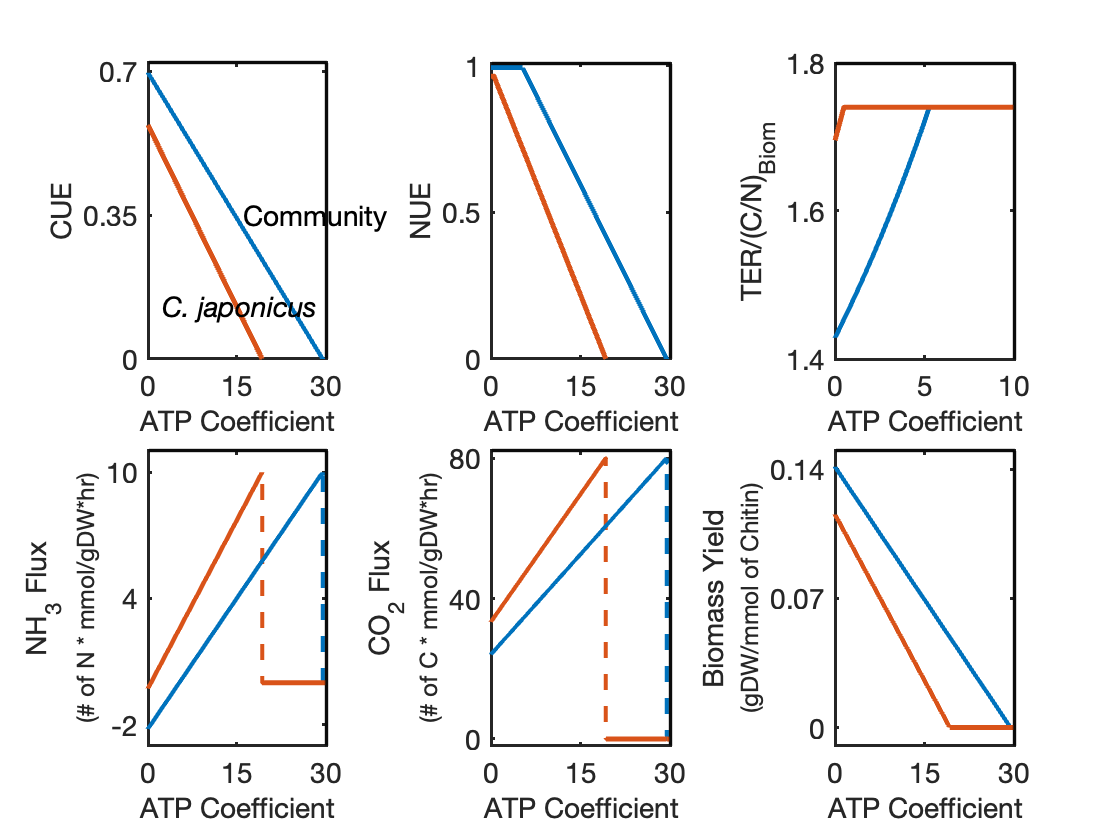

%Figure 5

clf
figure(5)

t = tiledlayout(2,3,"TileSpacing","compact");

nexttile
x = 0:0.01:30;
plot(x,CUEvals,'LineWidth',2.5,'LineStyle','-');
hold on;
plot(x,CUEvalsCJ,'LineWidth',2.5,'LineStyle','-');
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14)
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel('CUE', 'FontSize', 14);
xlim([0 30])
xticks([0 15 30])
ylim([0 0.72])
yticks([0 0.35 0.7])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
text(16,0.35,'Community','FontSize',14)
text(1,0.13,'{\it C. japonicus}','FontSize',14)
hold off

nexttile
x = 0:0.01:30;
plot(x,NUEvals,'LineWidth',2.5,'LineStyle','-');
hold on;
plot(x,NUEvalsCJ,'LineWidth',2.5,'LineStyle','-');
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14)
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel('NUE', 'FontSize', 14);
xlim([0 30])
xticks([0 15 30])
ylim([0 1.01])
yticks([0 0.5 1])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
hold off

nexttile
TERvalsComm = NUEvals./CUEvals;

x = 0:0.01:30;
plot(x,TERvalsComm,'LineWidth',2.5,'LineStyle','-');
hold on;
plot(x,TERvalsCJ,'LineWidth',2.5,'LineStyle','-');
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14)
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel('TER/(C/N)_B_i_o_m', 'FontSize', 14);
xlim([0 10])
xticks([0 5 10])
ylim([1.4 1.8])
yticks([1.4 1.6 1.8])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
hold off


nexttile
x = 0:0.01:30;
NH3Vals2 = NH3Vals;
NH3Vals2(2939) = 9.9489;
plot(x,NH3Vals2,'LineWidth',2,'LineStyle','--');
hold on;
plot(x,NH3ValsCJ,'LineWidth',2,'LineStyle','--');
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14)
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}NH_3 Flux';'\fontsize{12}(# of N * mmol/gDW*hr)'});
xticks([0 15 30])
ylim([-3 11])
yticks([-2 4 10])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')

NH3ValsDiff = NH3Vals2';
tol = 1;
yyDiffs  = diff(NH3ValsDiff);
yyDiffs = [0 yyDiffs]; %make same length as yy in lazy way
diffintolIndices = abs(yyDiffs) <tol;
x(~diffintolIndices)=NaN;
NH3ValsDiff(~diffintolIndices)=NaN;
plot(x,NH3ValsDiff,'LineWidth',2.5,'LineStyle','-','Color',[0 0.4470 0.7410]);

NH3ValsDiff2 = NH3ValsCJ';
tol = 1;
yyDiffs2  = diff(NH3ValsDiff2);
yyDiffs2 = [0 yyDiffs2]; %make same length as yy in lazy way
diffintolIndices = abs(yyDiffs2) <tol;
x(~diffintolIndices)=NaN;
NH3ValsDiff2(~diffintolIndices)=NaN;
plot(x,NH3ValsDiff2,'LineWidth',2.5,'LineStyle','-','Color',[0.8500 0.3250 0.0980]);
hold off

nexttile
CO2Vals = cFlux(11,:)';
CO2Vals(2939) = 79.6813;
CO2ValsCJ = cFluxCJ(48,:)';
x = 0:0.01:30;
plot(x,CO2Vals,'LineWidth',2,'LineStyle','--');
hold on;
plot(x,CO2ValsCJ,'LineWidth',2,'LineStyle','--');
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14)
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}CO_2 Flux';'\fontsize{12}(# of C * mmol/gDW*hr)'});
xticks([0 15 30])
ylim([-2 82])
yticks([0 40 80])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')

CO2ValsDiff = CO2Vals';
tol = 1;
yyDiffs  = diff(CO2ValsDiff);
yyDiffs = [0 yyDiffs]; %make same length as yy in lazy way
diffintolIndices = abs(yyDiffs) <tol;
x(~diffintolIndices)=NaN;
CO2ValsDiff(~diffintolIndices)=NaN;
plot(x,CO2ValsDiff,'LineWidth',2.5,'LineStyle','-','Color',[0 0.4470 0.7410]);

CO2ValsDiff2 = CO2ValsCJ';
tol = 1;
yyDiffs2  = diff(CO2ValsDiff2);
yyDiffs2 = [0 yyDiffs2]; %make same length as yy in lazy way
diffintolIndices = abs(yyDiffs2) <tol;
x(~diffintolIndices)=NaN;
CO2ValsDiff2(~diffintolIndices)=NaN;
plot(x,CO2ValsDiff2,'LineWidth',2.5,'LineStyle','-','Color',[0.8500 0.3250 0.0980]);
hold off

nexttile
x = 0:0.01:30;
plot(x,biomassVals,'LineWidth',2.5);
hold on;
plot(x,biomassValsCJ,'LineWidth',2.5)
set(gcf,'color','white')
set(gca,'LineWidth', 1.5,'FontSize',14)
xlabel('ATP Coefficient', 'FontSize', 14);
ylabel({'\fontsize{14}Biomass Yield';'\fontsize{12}(gDW/mmol of Chitin)'});
xticks([0 15 30])
ylim([-0.01 0.15])
yticks([0 0.07 0.14])
xline(max(xlim),'LineWidth',1.75,'Color','black')
yline(max(ylim),'LineWidth',1.75,'Color','black')
hold off

**Part 2**. **Exchange reactions between members of community**

%----------------------Values to Change-----------------------------------


MATmodel = 'Comm10_Model.mat';

chitinExRxn = 'EX_cpd11683_e0';
nagExRxn = 'EX_cpd00122_e0';
glcExRxn = 'EX_cpd00027_e0';
CO2ExRxn = 'EX_cpd00011_e0';
NH3ExRxn = 'EX_cpd00013_e0';

mediaRxns = {'EX_cpd00001_e0';'EX_cpd00007_e0';'EX_cpd00009_e0';'EX_cpd00011_e0';'EX_cpd00013_e0';...
    'EX_cpd00030_e0';'EX_cpd00034_e0';'EX_cpd00048_e0';'EX_cpd00058_e0';'EX_cpd00063_e0';...
    'EX_cpd00067_e0';'EX_cpd00099_e0';'EX_cpd00122_e0';'EX_cpd00149_e0';'EX_cpd00205_e0';'EX_cpd00244_e0';...
    'EX_cpd00254_e0';'EX_cpd00635_e0';'EX_cpd00971_e0';'EX_cpd03387_e0';'EX_cpd03396_e0';...
    'EX_cpd10515_e0';'EX_cpd10516_e0';'EX_cpd11574_e0';'EX_cpd11683_e0';'EX_cpd15574_e0'};

commBiom = 'bio1';
cjBiom = 'bio2';
ecBiom = 'bio3';

chitinLB = -10;
glcLB = 0;
nagLB = 0;
CO2LB = 0;
mediaLB = -1000;
mediaUB = 1000;
%-------------------------------------------------------------------------

We begin by loading that MATLAB model and finding necessary reactions that may come in handy later. We then find the individual pieces required for constraint-based modeling.

load(MATmodel)

%Carbon source reactions
idxChitinRxn = strcmp(model.rxns,chitinExRxn);
idxNAGRxn = strcmp(model.rxns,nagExRxn);
idxGlcRxn = strcmp(model.rxns,glcExRxn);

%NH3 reaction
idxNH3Rxn = find(strcmp(model.rxns,NH3ExRxn)); %Necessary as we want to see change in NH3 flux

%Biomass reaction
idxCommBiom = find(strcmp(model.rxns,commBiom));
idxCjBiom = find(strcmp(model.rxns,cjBiom));
idxEcBiom = find(strcmp(model.rxns,ecBiom));

%Fix upper and lower bounds of media -- begine with making all LBs of EX rxns 0 & UBs of EX rxns 1000
%Then we can readjust the LBs and UBs of media EX rxns only
idxExRxns = find(contains(model.rxns,'EX_'));
model.lb(idxExRxns) = 0;
model.ub(idxExRxns) = 1000;

for i = 1:length(mediaRxns)
    idxMediaRxn = find(strcmp(model.rxns,mediaRxns(i)));
    model.lb(idxMediaRxn) = mediaLB;
    model.ub(idxMediaRxn) = mediaUB;
end

%Make sure CO2 remains 0 (just to be sure)
idxCO2Rxn = find(strcmp(model.rxns,CO2ExRxn));
model.lb(idxCO2Rxn) = 0;

%Stop CO2 from being taken up
CO2_c1Met = find(contains(model.mets,"cpd00011_c1"));
CO2_c2Met = find(contains(model.mets,"cpd00011_c2"));
CO2_eMet = find(contains(model.mets,"cpd00011_e0"));

c1_CO2t = find(model.S(CO2_c1Met,:) ~= 0 & model.S(CO2_eMet,:) ~= 0); %c1 transport rxn
if model.S(CO2_eMet,c1_CO2t) < 0
    model.lb(c1_CO2t) = -1000;
    model.ub(c1_CO2t) = 0;
elseif model.S(CO2_eMet,c1_CO2t) > 0
    model.lb(c1_CO2t) = 0;
    model.ub(c1_CO2t) = 1000;
end

c2_CO2t = find(model.S(CO2_c2Met,:) ~= 0 & model.S(CO2_eMet,:) ~= 0); %c2 transport rxn
if model.S(CO2_eMet,c2_CO2t) < 0
    model.lb(c2_CO2t) = -1000;
    model.ub(c2_CO2t) = 0;
elseif model.S(CO2_eMet,c2_CO2t) > 0
    model.lb(c2_CO2t) = 0;
    model.ub(c2_CO2t) = 1000;
end

rxnIds = [];
%Find fluxes being produced and consumed (& shared) between the two isolates
metIdx = find(contains(model.mets,'_e0'));
metIdxFront = extractBefore(model.mets(metIdx),'_');
for i = 1:length(metIdx)
    vals = find(model.S(find(contains(model.mets,append(metIdxFront(i),'_e0'))),:) ~= 0);
    rxnIds = [rxnIds vals];
end
rxnIds = unique(rxnIds);
rxnIds = rxnIds(~ismember(rxnIds,idxExRxns));

Time to begin the loop performing FBA & pFBA for multiple values of ATP. We'll pull out the biomass value, NH3 flux, CUE & NUE.

% Get ATP terms for CH rxn
CHrxn = find(strcmp(model.rxns,'ChitinHydrolysis_c1'));

fluxesC1 = zeros(length(metIdxFront),4);
fluxesC2 = zeros(length(metIdxFront),4);

for i = 1:4
    
    l = [0 1.94 4.82 9.63];

    [m,n] = size(model.S); %Dimensions -- m = rows (metabolites) & n = col (reactions)

    %Add a column of zeros for new unknown, mu.
    Aeq = [model.S zeros(m,1)];

    %Add in the reaction that will set mu equal to each other:
    %V_CjBiom - 19*V_EcBiom = 0
    Aeq1 = [Aeq; zeros(1,n+1)];
    Aeq1(end,idxCjBiom) = 1;
    Aeq1(end,idxEcBiom) = -19;

    %Add in another reaction where V_CjBiom - 0.95mu = 0
    Aeq2 = [Aeq1; zeros(1,n+1)];
    Aeq2(end,idxCjBiom) = 1;
    Aeq2(end,end) = -0.95;

    %Add in another reaction where V_EcBiom - 0.05mu = 0
    Aeq3 = [Aeq2; zeros(1,n+1)];
    Aeq3(end,idxEcBiom) = 1;
    Aeq3(end,end) = -0.05;

    %Column of zeros that equal m of new Aeq (i.e., Aeq3)
    beq = zeros(size(Aeq3,1),1);

    %Update LBs and UBs
    Aeqlb = model.lb;
    Aeqlb(idxChitinRxn) = chitinLB;
    Aeqlb(idxNAGRxn) = nagLB;
    Aeqlb(idxGlcRxn) = glcLB;

    Aequb = model.ub;

    AeqlbNew = [Aeqlb; 0];
    AequbNew = [Aequb; 1000];

    Aineq = []; bineq = [];

    %Changing terms!!
    Aeq3(5,CHrxn) = l(i); %H+ term
    Aeq3(7,CHrxn) = -l(i); %ATP term
    Aeq3(10,CHrxn) = l(i); %ADP term
    Aeq3(11,CHrxn) = l(i); %Phosphate term
    Aeq3(37,CHrxn) = -l(i); %H2O term


    %Build Gurobi model using all above data;
    modelSolve.A = sparse([Aineq; Aeq3]);
    modelSolve.rhs = [bineq; beq];
    modelSolve.lb = AeqlbNew;
    modelSolve.ub = AequbNew;
    modelSolve.sense = [repmat('<',1,size(Aineq,1)) repmat('=',1,size(Aeq3,1))];

    f = zeros(1,size(Aeq3,2));
    f(end) = 1;
    modelSolve.modelsense = 'max';
    modelSolve.obj = f;

    params.outputflag = 0;
    params.FeasibilityTol = 1e-6;
    result = gurobi(modelSolve,params);
    mu = result.objval;

    j = round(100*i + 1); %Take the i value and make it whole numbers starting at 1

    %Now we perform pFBA by constraining the result.objval (biomass) and minimizing total flux
    if contains(result.status,'OPTIMAL')

        [m,n] = size(Aeq3);
        IrrevPosRxns = zeros(n,1);
        IrrevNegRxns = zeros(n,1);
        RevRxns = zeros(n,1);

        for k = 1:n
            if AeqlbNew(k) < 0 && AequbNew(k) > 0
                RevRxns(k) = 1;
            elseif AeqlbNew(k) < 0 && AequbNew(k) == 0
                IrrevNegRxns(k) = 1;
            elseif AeqlbNew(k) == 0 && AequbNew(k) > 0
                IrrevPosRxns(k) = 1;
            end
        end

        pAineqPRxns1 = zeros(n,2*n);
        pAineqPRxns2 = zeros(n,2*n);
        for l = 1:n
            if IrrevPosRxns(l) == 1
                pAineqPRxns1(l,l) = -1;
                pAineqPRxns2(l,l) = 1;
                pAineqPRxns2(l,n+l) = -1;
            end
        end
        pAineqPRxns1 = pAineqPRxns1(any(pAineqPRxns1,2),:);
        pAineqPRxns2 = pAineqPRxns2(any(pAineqPRxns2,2),:);

        pAineqNRxns1 = zeros(n,2*n);
        pAineqNRxns2 = zeros(n,2*n);
        for l = 1:n
            if IrrevNegRxns(l) == 1
                pAineqNRxns1(l,l) = 1;
                pAineqNRxns2(l,l) = -1;
                pAineqNRxns2(l,n+l) = -1;
            end
        end
        pAineqNRxns1 = pAineqNRxns1(any(pAineqNRxns1,2),:);
        pAineqNRxns2 = pAineqNRxns2(any(pAineqNRxns2,2),:);

        pAineqRRxns1 = zeros(n,2*n);
        pAineqRRxns2 = zeros(n,2*n);
        for l = 1:n
            if RevRxns(l) == 1
                pAineqRRxns1(l,l) = -1;
                pAineqRRxns1(l,n+l) = -1;
                pAineqRRxns2(l,l) = 1;
                pAineqRRxns2(l,n+l) = -1;
            end
        end
        pAineqRRxns1 = pAineqRRxns1(any(pAineqRRxns1,2),:);
        pAineqRRxns2 = pAineqRRxns2(any(pAineqRRxns2,2),:);

        pAineq = [pAineqPRxns1; pAineqPRxns2; pAineqNRxns1; pAineqNRxns2; pAineqRRxns1; pAineqRRxns2];
        pbineq = zeros(size(pAineq,1),1);

        pAeq = [Aeq3 zeros(m,n)];
        pbeq = zeros(size(pAeq,1),1);

        modelP.A = sparse([pAineq; pAeq]);
        modelP.rhs = [pbineq; pbeq];
        modelP.sense = [repmat('<',1,size(pAineq,1)) repmat('=',1,size(pAeq,1))];

        modelP.lb = [AeqlbNew; zeros(n,1)];
        modelP.ub = [AequbNew; 1000*ones(n,1)];
        modelP.lb(idxCjBiom) = result.x(idxCjBiom);
        modelP.ub(idxCjBiom) = result.x(idxCjBiom);
        modelP.lb(idxEcBiom) =result.x(idxEcBiom);
        modelP.ub(idxEcBiom) = result.x(idxEcBiom);

        f = [zeros(1,n) ones(1,n)];
        modelP.obj = f;
        modelP.modelsense = 'min';

        params.outputflag = 0;
        params.FeasibilityTol = 1e-6;
        resultP = gurobi(modelP,params); %Pull out flux solution for pFBA

        if contains(resultP.status,'OPTIMAL')
            for j = 1:length(rxnIds)
                for k = 1:length(metIdxFront)
                    if contains(model.rxns(rxnIds(j)),'_c1') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) < 0 && resultP.x(rxnIds(j)) > 0
                        fluxesC1(k,i) = fluxesC1(k,i) - resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c1') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) < 0 && resultP.x(rxnIds(j)) < 0
                        fluxesC1(k,i) = fluxesC1(k,i) - resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c1') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) > 0 && resultP.x(rxnIds(j)) > 0
                        fluxesC1(k,i) = fluxesC1(k,i) + resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c1') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) > 0 && resultP.x(rxnIds(j)) < 0
                        fluxesC1(k,i) = fluxesC1(k,i) + resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c2') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) < 0 && resultP.x(rxnIds(j)) > 0
                        fluxesC2(k,i) = fluxesC2(k,i) - resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c2') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) < 0 && resultP.x(rxnIds(j)) < 0
                        fluxesC2(k,i) = fluxesC2(k,i) - resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c2') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) > 0 && resultP.x(rxnIds(j)) > 0
                        fluxesC2(k,i) = fluxesC2(k,i) + resultP.x(rxnIds(j));
                    elseif contains(model.rxns(rxnIds(j)),'_c2') == 1 && model.S(find(contains(model.mets,append(metIdxFront(k),'_e0'))),rxnIds(j)) > 0 && resultP.x(rxnIds(j)) < 0
                        fluxesC2(k,i) = fluxesC2(k,i) + resultP.x(rxnIds(j));
                    end
                end
            end 
        end
    end
end
FluxTable = table(extractBefore(model.mets(metIdx),'_'),model.metNames(metIdx),model.metFormulas(metIdx),fluxesC1,fluxesC2,'VariableNames',{'MetID','Metabolite','Formula','c1Flux','c2Flux'});
FluxTable(sum(FluxTable.c1Flux == 0,2) == 4 & sum(FluxTable.c2Flux == 0,2) == 4,:) = [];
for i = 1:length(FluxTable.Metabolite)
    if contains(FluxTable.Metabolite(i),'_')
        FluxTable.Metabolite(i) = extractBefore(FluxTable.Metabolite(i),'_');
    end
end

for i = 1:length(FluxTable.Metabolite)
    if contains(FluxTable.Formula(i),'C') && cell2mat(isstrprop(extract(extractAfter(FluxTable.Formula(i),'C'),1),'lower')) == 0
        FluxTable.Organic(i) = 1;
    else
        FluxTable.Organic(i) = 0;
    end
end

FluxTable = sortrows(FluxTable,4);


FluxTable(5,:) = [];

FluxTable

FluxTable.c1Flux(52,1) = -FluxTable.c1Flux(52,1);
FluxTable.c1Flux(52,2) = -FluxTable.c1Flux(52,2);
FluxTable.c1Flux(52,3) = -FluxTable.c1Flux(52,3);
FluxTable.c1Flux(52,4) = -FluxTable.c1Flux(52,4);

FluxTable.c2Flux(52,1) = -FluxTable.c2Flux(52,1);
FluxTable.c2Flux(52,2) = -FluxTable.c2Flux(52,2);
FluxTable.c2Flux(52,3) = -FluxTable.c2Flux(52,3);
FluxTable.c2Flux(52,4) = -FluxTable.c2Flux(52,4);

%Bar graph:

idx1 = find(FluxTable.Organic == 1);
idx2 = find(FluxTable.Organic == 0);


y1 = sign(FluxTable.c1Flux).*log10(1+abs(FluxTable.c1Flux)/10^-3);
y2 = sign(FluxTable.c2Flux).*log10(1+abs(FluxTable.c2Flux)/10^-3);

figure
t = tiledlayout(2,3,'TileSpacing','Compact');

nexttile([1 2])
ax1 = gca();
hold on
box on
set(gcf,'color','w');

ax1.LineWidth = 1.5;
bar(y1(idx1,:),'EdgeColor','k')
set(ax1,'XTick',1:length(FluxTable.Metabolite(idx1)),'XTickLabel',[],'FontSize',14,'box','off')
ylim([-5 5])
yline(max(ylim),'LineWidth',1.75,'Color','black')
yyaxis left
yticks([-4 -3 -2 -1 0 1 2 3 4])
yticklabels({'-10','-1','-0.1','-0.01','0','0.01','0.1','1','10'})
ylabel({'\fontsize{16}Flux of {\it C. japonicus}';'\fontsize{14}(mmol/gDW*hr)'});
yyaxis right
yticks([0.25 0.75])
yticklabels({'',''})
ytickangle(90)
ax1.YAxis(2).TickLength = [0 0];
ax1.YAxis(2).Color = 'k';
lgd = legend('0% (ATP coeff = 0)','10% (ATP coeff = 1.93)','25% (ATP coeff = 4.81)','50% (ATP coeff = 9.62)'); 
legend('boxoff')
title(lgd,'Decrease in biomass yield:') 
hold off

nexttile
ax1 = gca();
hold on
box on
set(gcf,'color','w');

ax1.LineWidth = 1.5;
bar(y1(idx2,:),'EdgeColor','k')
set(ax1,'XTick',1:length(FluxTable.Metabolite(idx2)),'XTickLabel',[],'FontSize',14,'box','off')
ylim([-5 5])
yline(max(ylim),'LineWidth',1.75,'Color','black')
yyaxis left
yticks([-4 -3 -2 -1 0 1 2 3 4])
yticklabels([])
yyaxis right
yticks([0.25 0.75])
yticklabels({'Consumed','Produced'})
ytickangle(90)
ax1.YAxis(2).TickLength = [0 0];
ax1.YAxis(2).Color = 'k';
hold off

nexttile([1 2])
ax1 = gca();
hold on
box on
set(gcf,'color','w');

ax1.LineWidth = 1.5;
bar(y2(idx1,:),'EdgeColor','k')
set(ax1,'XTick',1:length(FluxTable.Metabolite(idx1)),'XTickLabel',FluxTable.Metabolite(idx1),'FontSize',14,'box','off');
ylim([-5 5])
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('Organic Metabolites','FontSize',16)
yyaxis left
yticks([-4 -3 -2 -1 0 1 2 3 4])
yticklabels({'-10','-1','-0.1','-0.01','0','0.01','0.1','1','10'})
ylabel({'\fontsize{16}Flux of {\it E. coli}';'\fontsize{14}(mmol/gDW*hr)'});
yyaxis right
yticks([0.25 0.75])
yticklabels({'',''})
ytickangle(90)
ax1.YAxis(2).TickLength = [0 0];
ax1.YAxis(2).Color = 'k';
hold off

nexttile
ax1 = gca();
hold on
box on
set(gcf,'color','w');

ax1.LineWidth = 1.5;
bar(y2(idx2,:),'EdgeColor','k')
set(ax1,'XTick',1:length(FluxTable.Metabolite(idx2)),'XTickLabel',FluxTable.Metabolite(idx2),'FontSize',14,'box','off');
ylim([-5 5])
yline(max(ylim),'LineWidth',1.75,'Color','black')
xlabel('Inorganic Metabolites','FontSize',16)
yyaxis left
yticks([-4 -3 -2 -1 0 1 2 3 4])
yticklabels([])
yyaxis right
yticks([0.25 0.75])
yticklabels({'Consumed','Produced'})
ytickangle(90)
ax1.YAxis(2).TickLength = [0 0];
ax1.YAxis(2).Color = 'k';
hold off